# **法拉第电磁感应定律**

**        本小节通过分析带电导线周围的电场、磁场，帮助学生理解法拉第电磁感应定律。**

- **电场**

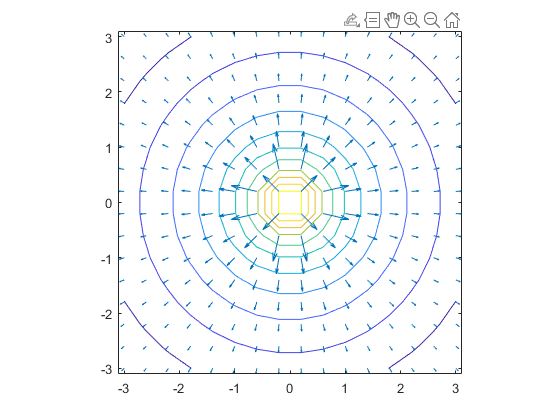

[X,Y] = meshgrid(-3:.4:3,-3:.4:3);      %设置绘制区域的网格
phi = -log(X.^2 +Y.^2);                	%给出电势的表达式，忽略系数
[EX,EY] = gradient(-phi,.4,.4);         %利用数值方法求电势的负梯度，得到电场强度
figure(1)
contour(X,Y,phi);                    	%绘制等势线
hold on                             	%叠加绘图模式，后面绘制的图与前面的图叠加
quiver(X,Y,EX,EY);                   	%在网格中绘制电力线
axis image;                         	%x、y方向等比例显示，不做拉伸、压缩处理
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **磁场**

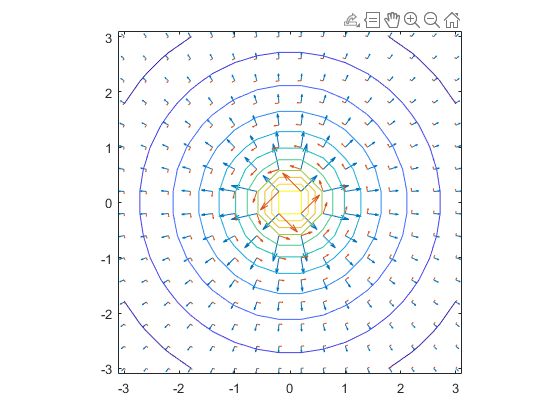

figure(2)
contour(X,Y,phi);                    	%绘制等势线
hold on                             	%叠加绘图模式，后面绘制的图与前面的图叠加
BX=-Y./(X.^2+Y.^2);
BY=X./(X.^2+Y.^2);
quiver(X,Y,BX,BY)                       %在网格中绘制磁力线
axis image;                         	%x、y方向等比例显示，不做拉伸、压缩处理